# Cleanup

clearvars
close all
clc

## Generate cuboid beacon

n_points = 8;
points = [25 25 35 35 25 25 35 35; 25 25 25 25 35 35 35 35; 8 4 8 4 8 4 8 4] * 0.5;
center = mean(points, 2);

## Plot beacon features

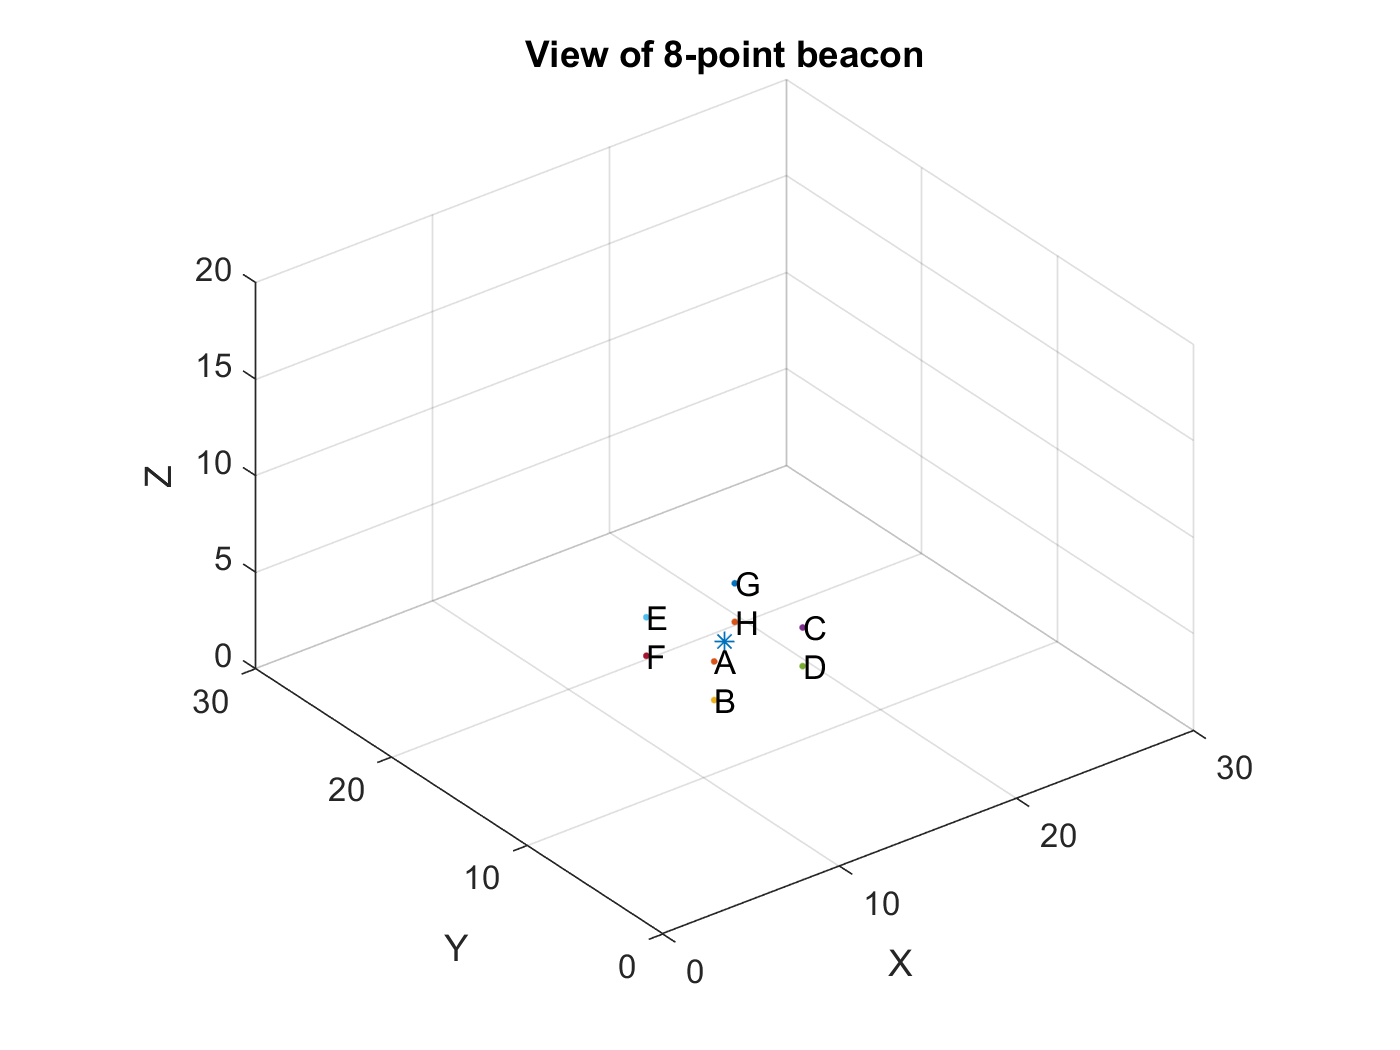

fig = figure('name', 'beacon');
scatter3(center(1), center(2), center(3), 'Marker', '*', 'HandleVisibility','off');
hold on
for  j = 1:n_points
    scatter3(points(1,j), points(2,j), points(3,j) , 'Marker' , '.', 'HandleVisibility','off');
    text(points(1,j), points(2,j), points(3,j), char('@'+ j));
    hold on;
end
title("View of " + n_points + "-point beacon")
axis equal
xlabel 'X'
ylabel 'Y'
zlabel 'Z'
xlim([0 30])
ylim([0 30])
zlim([0 20])

## Parameters

r0 = 15;
x0 = center(1);
y0 = center(2) - r0;
z0 = center(3);
N = 13; % N of photos
gamma_E = 0.005; % uniform noise coefficient for E poison
gamma_photo = 0.01; % uniform noise coefficient for photos

## Run Simulink

USE_SIMULINK = true;
radius_tolerance = 0.8; % determines when to start considering circular motion

if ~USE_SIMULINK
    %% Simulate running the script, and you get coords_x,coords_y,thetas as variables
    disp("Generating trajectory manually")
    n_samples = 1000;
    thetas = (0:1/n_samples:1 - 1/n_samples) * 360;
    circle = center + [r0 * cos(deg2rad(thetas)); r0 * sin(deg2rad(thetas)); zeros(1, n_samples)];
    coords_x = circle(1, :);
    coords_y = circle(2, :);
else
    %% Otherwise just filter input data
    disp("Using simulink simulation")
    %run def_trajectory.m
    load data.mat
    coords_x = x_out';
    coords_y = y_out';
    n_samples = length(coords_x);
    %% Find start of circular motion
    for i = 1:n_samples
        curr_norm = norm(coords_x(i), coords_y(i));
        if curr_norm > radius_tolerance * r0
            start_sample = i;
            break;
        end
    end
    coords_x = coords_x + center(1);
    coords_y = coords_y + center(2);
    coords_z = ones(1, n_samples)*center(3);
    thetas = rad2deg(theta_out(start_sample:end))';
    n_samples = length(coords_x) - start_sample + 1;
    seg_coords_x = coords_x(:,start_sample:end);
    seg_coords_y = coords_y(:,start_sample:end);
    seg_coords_z = center(3) * ones(1, n_samples);
end

Using simulink simulation


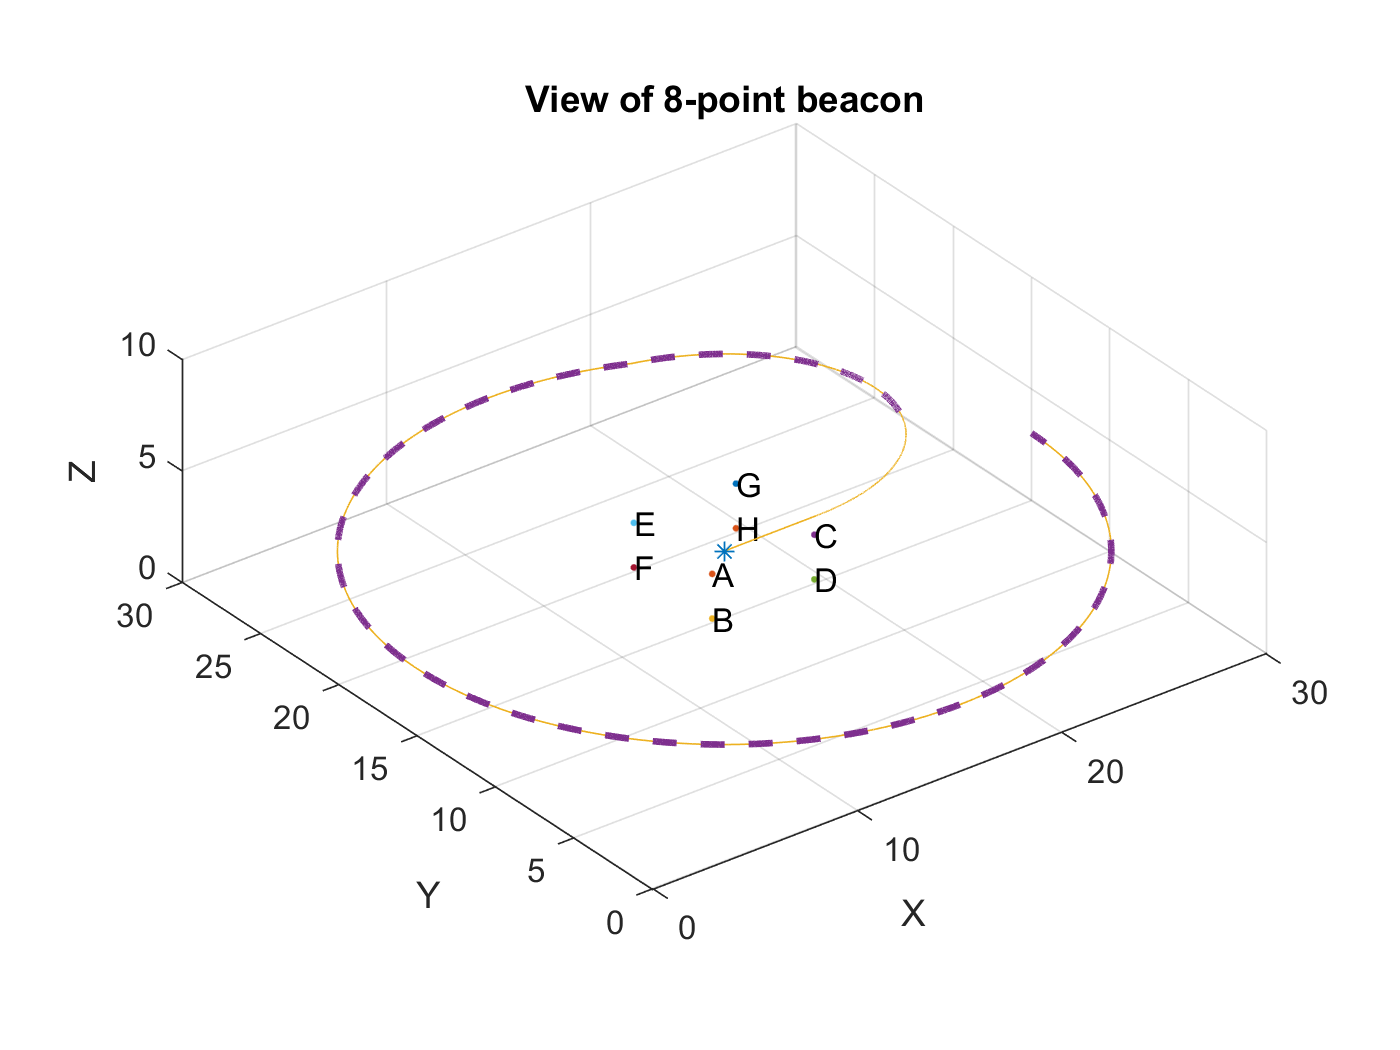

grid on
axis equal
hold on
plot3(center(1) + x_out', center(2) + y_out', coords_z)
plot3(seg_coords_x, seg_coords_y, seg_coords_z, "--", "LineWidth", 2)
view(3)
zlim([0 10])

## Get absolute measurements (T, R) from cartesian points

shoots_interval = ceil(n_samples / N);
saggi_angles = thetas(1:shoots_interval:end);
saggi_angles = wrapTo360(saggi_angles);
T_history_abs = [seg_coords_x(1:shoots_interval:end); seg_coords_y(1:shoots_interval:end); z0 * ones(1,N)];
%% Calculate the pose of camera wrt absolute frame
R_history_abs = zeros(3,3,N);
cam_angles = zeros(1,N);
for i = 1:N
    R_history_abs(:, :, i) = getRfromZ(T_history_abs(:,i), center);
    m = rotm2eul(R_history_abs(:,:,i));
    cam_angles(i) = wrapTo360(rad2deg(m(1)) + 90);
end
delta_cam_sag = wrapTo360(cam_angles - saggi_angles);

## Trajectory parameters

Rwb = R_history_abs(:,:,1); % Initial pose of camera (body 2 word)
Rbw = Rwb'; % Initial pose of camera (word 2 body)
Twb = T_history_abs(:,1,1); % Initial position of camera
Tbw = -Twb;

## Initial position plot

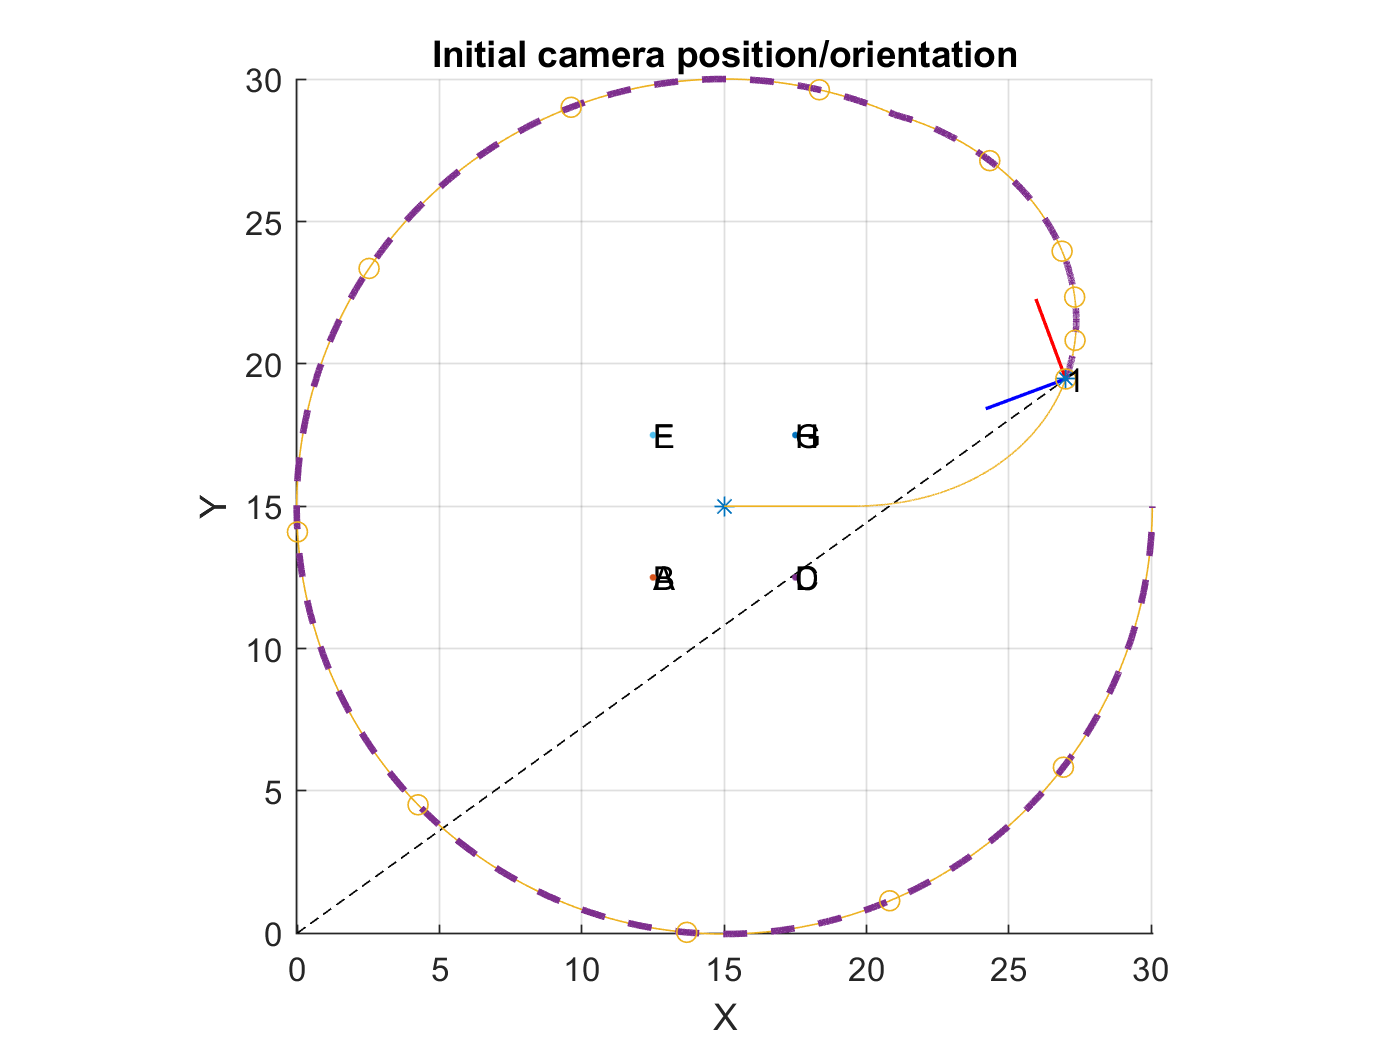

hold on
triad('Parent',gca,'Scale',3,'LineWidth',1,'Tag','#1','Matrix', [Rwb Twb; 0 0 0 1]);
scatter3(Twb(1), Twb(2), Twb(3), 'Marker',"*", 'HandleVisibility','off')
quiver3(0, 0, 0, Twb(1), Twb(2), Twb(3), "AutoscaleFactor", 1, 'HandleVisibility','off', 'Color', 'k', 'LineStyle','--', "ShowArrowHead", 'off');
scatter3(T_history_abs(1,:), T_history_abs(2,:), T_history_abs(3,:), "Marker", "o")
text(Twb(1), Twb(2), Twb(3), "1");
view(3)
zlim([0 15])
grid on
xlabel 'X'
ylabel 'Y'
zlabel 'Z'
title("Initial camera position/orientation");
view(2)

## Trajectory generation and plotting

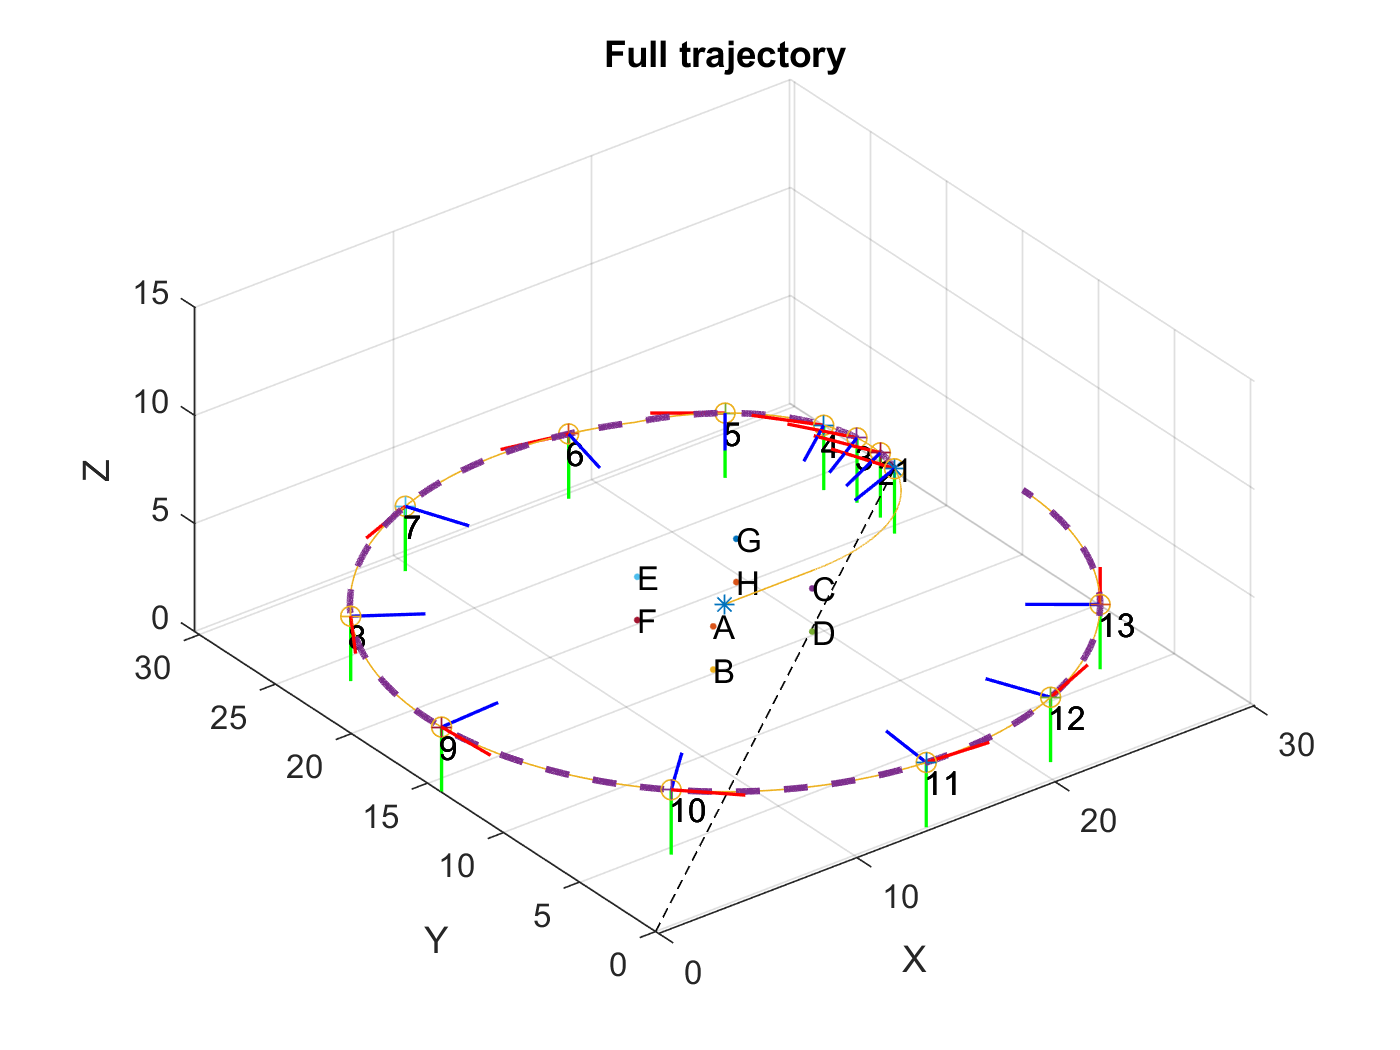

for i = 2:N
    R0i = R_history_abs(:,:,i);
    T0i = T_history_abs(:,i);
    triad('Parent',gca,'Scale',3,'LineWidth',1,'Tag',"#" + i ,'Matrix', [R0i T0i; 0 0 0 1]);
    scatter3(T0i(1) , T0i(2) , T0i(3) , 'Marker' , '+', 'HandleVisibility','off');
    text(T0i(1) - [0.5 0.5 0.5], T0i(2) - [0.5 0.5 0.5], T0i(3) - [0.5 0.5 0.5], "" + i);
    hold on
end

for i = 1:N
    if i == N
        j = 1;
    else
        j = i + 1;
    end
end
zlim([0 15])
view(3)
daspect([1 1 1])
grid on
xlabel 'X'
ylabel 'Y'
zlabel 'Z'
title("Full trajectory");

## Generate E from R and T (until we can figure out E estimation)

E_history = zeros(3,3,N,N); % create a cell array equal to the number of poses
EN_history = zeros(3,3,N,N); % same for noisy E
GT_rel_T = zeros(3,1,N,N);
GT_rel_T_norm = zeros(3,1,N,N);
GT_rel_R = zeros(3,3,N,N);

for i = 1:N
    for j = 1:N
        if j == i
            GT_rel_R(:,:, i, j) = eye(3);
            GT_rel_T(:,:, i, j) = zeros(3,1);
            continue
        else
            R_ij = axang2rotm([0 1 0 deg2rad(cam_angles(j) - cam_angles(i))]);
        end
        T_ij =  R_ij' *(T_history_abs(:, j) - T_history_abs(:, i)); %
        E = getSkew(T_ij) * R_ij;
        GT_rel_T(:,:, i, j) = T_ij;
        GT_rel_T_norm(:, :, i, j) = T_ij / norm(T_ij);
        GT_rel_R(:,:, i, j) = R_ij;
        E = E / norm(E); % normalize to lose scale
        E_noisy = E + gamma_E*rand(3, 3); % poison E matrix with noise to simulate reconstruction error
        E_history(:,:, i, j) = E;
        EN_history(:,:, i, j) = E_noisy;
    end
end

## Compute R, T from E

R1_rel = zeros(3,3,N,N);
T1_rel = zeros(3,1,N,N);
R2_rel = zeros(3,3,N,N);
T2_rel = zeros(3,1,N,N);

for i = 1:N
    for j = 1:N
        if i == j; continue; end
        %Compute R_ij and T_ij
        %E = E_history(:,:, i, j); % Extract E_ij
        E = EN_history(:,:, i, j); % Uncomment to to use noisy
        [U, S, V] = svd(E); % Singular value decomp
        % Safeguard against non SO(3) matrix
        if (det(U)<0)
            U = [U(:,1) U(:,2) -U(:,3)];
        end
        if (det(V)<0)
            V = [V(:,1) V(:,2) -V(:,3)]; 
        end
        sigmas = diag(S); % Get singular values
        avg = (sigmas(1) + sigmas(2)) / 2; % Average values
        sigmas = [avg; avg; 0]; % Substitute
        S = diag(sigmas);
        Rp = [cos(pi/2) -sin(pi/2) 0; sin(pi/2) cos(pi/2) 0; 0 0 1]; % Rotation of pi/2 around z axis
        Rm = [cos(-pi/2) -sin(-pi/2) 0; sin(-pi/2) cos(-pi/2) 0; 0 0 1]; % Rotation of -pi/2 around z axis
        skewT1 = U * Rp * S * U'; % Get T matrix
        currT1 = getT(skewT1); % Get T from T matrix
        currT2 = -getT(skewT1);
        currR1 = U * Rp' * V'; % Get R matrix
        currR2 = U * Rm' * V';
        R1_rel(:,:, i, j) = currR1; % Save data
        T1_rel(:,:, i, j) = currT1;
        R2_rel(:,:, i, j) = currR2;
        T2_rel(:,:, i, j) = currT2;
    end
end

## Perspective projection of points (photos simulation)

PI0 = [eye(3) zeros(3,1)]; % standard projection matrix
K_f = eye(3); % unitary focal length
K_s = [1 0 0; 0 1 0; 0 0 1]; % ideal, no distortion
K = K_s * K_f;
im_planes_norm = zeros(3, n_points, N); % normalized points for each view
im_planes_noisy = zeros(3, n_points, N); % noisy normalized points for each view (actual photos)
centers_norm = zeros(3, N);
centers_noisy = zeros(3,N);

for i = 1:N
    f = figure('name', "photo" + i);
    R0i = R_history_abs(:, :, i);
    T0i = T_history_abs(:, i);
    Ri0 = R0i';
    Ti0 = -T0i;
    g = [Ri0 Ri0*Ti0; 0 0 0 1];
    proj_c_og = K * PI0 * g * [center; 1];
    proj_c_norm = proj_c_og / proj_c_og(3);
    centers_norm(:, i) = proj_c_norm;
    centers_noisy(:, i) = proj_c_norm + [gamma_photo * rand(2,1); 0];
    scatter(proj_c_norm(1), proj_c_norm(2), 200, "Marker", "pentagram");
    text(proj_c_norm(1), proj_c_norm(2), "C", "Fontsize", 8, "HorizontalAlignment","center","FontWeight","bold");
    hold on
    grid on
    for j = 1:n_points
        im_point = K * PI0 * g * [points(:,j); 1];
        im_planes_norm(:, j, i) = im_point / im_point(3);
        im_planes_noisy(:, j, i) = im_point / im_point(3) + [gamma_photo*rand(2,1); 0];
        scatter(im_planes_noisy(1, j, i), im_planes_noisy(2, j, i), 36, "Marker", ".");
        scatter(im_planes_norm(1, j, i), im_planes_norm(2, j, i), 90, "Marker", "square");
        text(im_planes_norm(1, j, i), im_planes_norm(2, j, i), char('@'+ j), "Fontsize", 8, "HorizontalAlignment","center");
    end
    title("Image on pose #" + i);
    set(gca, 'YDir','reverse')
    close(f)
end

## Reconstruct camera center (beacon center) from center using all photos in single view (cuboid case)

est_dist = zeros(N,1);
for i = 1:N
    AB_3D = norm(points(:, 2) - points(:,1));
    CD_3D = norm(points(:, 4) - points(:,3));
    EF_3D = norm(points(:, 6) - points(:,5));
    GH_3D = norm(points(:, 8) - points(:,7));
    AB = norm(im_planes_noisy(:,2,i)- im_planes_noisy(:,1,i));
    CD = norm(im_planes_noisy(:,4,i)- im_planes_noisy(:,3,i));
    EF = norm(im_planes_noisy(:,6,i)- im_planes_noisy(:,5,i));
    GH = norm(im_planes_noisy(:,8,i)- im_planes_noisy(:,7,i));
    Z_AB = AB_3D / AB;
    Z_CD = CD_3D / CD;
    Z_EF = EF_3D / EF;
    Z_GH = GH_3D / GH;
    Z_CENTER = mean([Z_AB, Z_CD, Z_EF, Z_GH]);
    est_dist(i) = Z_CENTER;
end

est_r0 = mean(est_dist);
est_center = [x0; y0 + est_r0; z0];

## Pose discrimination via triangulation (!!! NOT WORKING AT ALL !!!)

cam = cameraParameters("IntrinsicMatrix", K);
R_rel = zeros(3,3,N,N);
T_rel = zeros(3,1,N,N);
for i = 1:N-1
    for j = 1:N 
     i
     j %= i+1
        if i == j
            R_rel(:, :, i, j) = eye(3);
            R1_rel(:, :, i, j) = eye(3);
            R2_rel(:, :, i, j) = eye(3);
            T_rel(:, :, i, j) = zeros(3,1);
            T1_rel(:, :, i, j) = zeros(3,1);
            T2_rel(:, :, i, j) = zeros(3,1);
            continue
        end
        best = 0;
        % Case 1 R1 T1
        % Extract R12 and T12 matrices
        R = R1_rel(:,:, i, j);
        T = T1_rel(:,:, i, j);
        

        % Configure foward extrinsic
        sParams = stereoParameters(cam, cam, R, T);   %(R, -T) and (R' , -T) are OK
        % Triangulate points in frame 1
        pnts1 = (triangulate(im_planes_noisy(1:2,:,i)', im_planes_noisy(1:2,:,j)', sParams)); %points expressed wrt the reference frame of camera i-1
        sParams = stereoParameters(cam, cam, R', -R' * T);
        pnts2 = (triangulate(im_planes_noisy(1:2,:,j)', im_planes_noisy(1:2,:,i)', sParams));
        % Count positive occurences in z for both
        votes = nnz((double(pnts1(:,3)) > 0 & double(pnts2(:,3)) > 0))
        
        % If better result than previous
        if votes > best
            % Update best result
            best = votes;
            %fprintf("Filled cell [%i,%i] with %i/%i votes\n", i, j, best, n_points);
            % Save R12, T12 as correct
            R_rel(:,:, i, j) = R;
            T_rel(:,:, i, j) = T;
        end
        % Case 2 R1 T2
        R = R1_rel(:,:, i, j);
        T = T2_rel(:,:, i, j);
        
        % Configure foward extrinsic
        sParams = stereoParameters(cam, cam, R, T);   %(R, -T) and (R' , -T) are OK
        % Triangulate points in frame 1
        pnts1 = (triangulate(im_planes_noisy(1:2,:,i)', im_planes_noisy(1:2,:,j)', sParams)); %points expressed wrt the reference frame of camera i-1
        sParams = stereoParameters(cam, cam, R', -R' * T);
        pnts2 = (triangulate(im_planes_noisy(1:2,:,j)', im_planes_noisy(1:2,:,i)', sParams));
        % Count positive occurences in z for both
        votes = nnz((double(pnts1(:,3)) > 0 & double(pnts2(:,3)) > 0))
        
        if votes > best
            best = votes;
            %fprintf("Filled cell [%i,%i] with %i/%i votes\n", i, j, best, n_points);
            R_rel(:,:, i, j) = R;
            T_rel(:,:, i, j) = T;
        end
        % Case 3 R2 T1
        R = R2_rel(:,:, i, j);
        T = T1_rel(:,:, i, j);
        
        % Configure foward extrinsic
        sParams = stereoParameters(cam, cam, R, T);   %(R, -T) and (R' , -T) are OK
        % Triangulate points in frame 1
        pnts1 = (triangulate(im_planes_noisy(1:2,:,i)', im_planes_noisy(1:2,:,j)', sParams)); %points expressed wrt the reference frame of camera i-1
        sParams = stereoParameters(cam, cam, R', -R' * T);
        pnts2 = (triangulate(im_planes_noisy(1:2,:,j)', im_planes_noisy(1:2,:,i)', sParams));
        % Count positive occurences in z for both
        votes = nnz((double(pnts1(:,3)) > 0 & double(pnts2(:,3)) > 0))
        
        
        if votes > best
            best = votes;
            %fprintf("Filled cell [%i,%i] with %i/%i votes\n", i, j, best, n_points);
            R_rel(:,:, i, j) = R;
            T_rel(:,:, i, j) = T;
        end
        % Case 4 R2 T2
        R = R2_rel(:,:, i, j);
        T = T2_rel(:,:, i, j);
        
        
        % Configure foward extrinsic
        sParams = stereoParameters(cam, cam, R, T);   %(R, -T) and (R' , -T) are OK
        % Triangulate points in frame 1
        pnts1 = (triangulate(im_planes_noisy(1:2,:,i)', im_planes_noisy(1:2,:,j)', sParams)); %points expressed wrt the reference frame of camera i-1
        sParams = stereoParameters(cam, cam, R', -R' * T);
        pnts2 = (triangulate(im_planes_noisy(1:2,:,j)', im_planes_noisy(1:2,:,i)', sParams));
        % Count positive occurences in z for both
        votes = nnz((double(pnts1(:,3)) > 0 & double(pnts2(:,3)) > 0))
        
        
        if votes > best
            best = votes;
            %fprintf("Filled cell [%i,%i] with %i/%i votes\n", i, j, best, n_points);
            R_rel(:,:, i, j) = R;
            T_rel(:,:, i, j) = T;
        end
    end
end

i = 1

j = 1

i = 1

j = 2

votes = 8

votes = 0

votes = 0

votes = 0

i = 1

j = 3

votes = 6

votes = 1

votes = 0

votes = 0

i = 1

j = 4

votes = 2

votes = 5

votes = 0

votes = 0

i = 1

j = 5

votes = 0

votes = 0

votes = 8

votes = 0

i = 1

j = 6

votes = 0

votes = 0

votes = 0

votes = 0

i = 1

j = 7

votes = 0

votes = 0

votes = 0

votes = 4

i = 1

j = 8

votes = 0

votes = 1

votes = 0

votes = 8

i = 1

j = 9

votes = 0

votes = 0

votes = 0

votes = 8

i = 1

j = 10

votes = 0

votes = 0

votes = 3

votes = 0

i = 1

j = 11

votes = 0

votes = 8

votes = 0

votes = 8

i = 1

j = 12

votes = 0

votes = 3

votes = 0

votes = 0

i = 1

j = 13

votes = 1

votes = 1

votes = 0

votes = 0

i = 2

j = 1

votes = 0

votes = 0

votes = 0

votes = 8

i = 2

j = 2

i = 2

j = 3

votes = 0

votes = 8

votes = 0

votes = 0

i = 2

j = 4

votes = 0

votes = 8

votes = 0

votes = 0

i = 2

j = 5

votes = 0

votes = 8

votes = 0

votes = 0

i = 2

j = 6

votes = 0

votes = 0

votes = 2

votes = 0

i = 2

j = 7

votes = 0

votes = 0

votes = 0

votes = 4

i = 2

j = 8

votes = 0

votes = 1

votes = 0

votes = 8

i = 2

j = 9

votes = 8

votes = 0

votes = 0

votes = 0

i = 2

j = 10

votes = 1

votes = 0

votes = 4

votes = 0

i = 2

j = 11

votes = 0

votes = 8

votes = 0

votes = 8

i = 2

j = 12

votes = 0

votes = 5

votes = 0

votes = 0

i = 2

j = 13

votes = 1

votes = 2

votes = 0

votes = 0

i = 3

j = 1

votes = 0

votes = 0

votes = 2

votes = 6

i = 3

j = 2

votes = 0

votes = 8

votes = 0

votes = 0

i = 3

j = 3

i = 3

j = 4

votes = 0

votes = 8

votes = 0

votes = 0

i = 3

j = 5

votes = 0

votes = 8

votes = 0

votes = 0

i = 3

j = 6

votes = 0

votes = 0

votes = 3

votes = 0

i = 3

j = 7

votes = 1

votes = 0

votes = 0

votes = 2

i = 3

j = 8

votes = 0

votes = 0

votes = 0

votes = 8

i = 3

j = 9

votes = 8

votes = 0

votes = 0

votes = 0

i = 3

j = 10

votes = 0

votes = 3

votes = 0

votes = 0

i = 3

j = 11

votes = 0

votes = 7

votes = 0

votes = 8

i = 3

j = 12

votes = 0

votes = 5

votes = 0

votes = 0

i = 3

j = 13

votes = 1

votes = 2

votes = 0

votes = 0

i = 4

j = 1

votes = 2

votes = 6

votes = 0

votes = 0

i = 4

j = 2

votes = 0

votes = 8

votes = 0

votes = 0

i = 4

j = 3

votes = 0

votes = 8

votes = 0

votes = 0

i = 4

j = 4

i = 4

j = 5

votes = 0

votes = 8

votes = 0

votes = 0

i = 4

j = 6

votes = 0

votes = 0

votes = 6

votes = 0

i = 4

j = 7

votes = 3

votes = 0

votes = 0

votes = 0

i = 4

j = 8

votes = 0

votes = 0

votes = 0

votes = 8

i = 4

j = 9

votes = 6

votes = 0

votes = 0

votes = 0

i = 4

j = 10

votes = 0

votes = 1

votes = 0

votes = 0

i = 4

j = 11

votes = 0

votes = 4

votes = 0

votes = 8

i = 4

j = 12

votes = 0

votes = 5

votes = 0

votes = 5

i = 4

j = 13

votes = 0

votes = 0

votes = 0

votes = 0

i = 5

j = 1

votes = 0

votes = 8

votes = 0

votes = 0

i = 5

j = 2

votes = 0

votes = 8

votes = 0

votes = 0

i = 5

j = 3

votes = 0

votes = 8

votes = 0

votes = 0

i = 5

j = 4

votes = 0

votes = 8

votes = 0

votes = 0

i = 5

j = 5

i = 5

j = 6

votes = 0

votes = 0

votes = 8

votes = 0

i = 5

j = 7

votes = 3

votes = 4

votes = 0

votes = 0

i = 5

j = 8

votes = 2

votes = 0

votes = 0

votes = 6

i = 5

j = 9

votes = 0

votes = 2

votes = 0

votes = 5

i = 5

j = 10

votes = 0

votes = 0

votes = 1

votes = 0

i = 5

j = 11

votes = 7

votes = 0

votes = 1

votes = 0

i = 5

j = 12

votes = 0

votes = 0

votes = 0

votes = 8

i = 5

j = 13

votes = 0

votes = 0

votes = 0

votes = 4

i = 6

j = 1

votes = 0

votes = 0

votes = 0

votes = 0

i = 6

j = 2

votes = 0

votes = 0

votes = 1

votes = 0

i = 6

j = 3

votes = 0

votes = 0

votes = 4

votes = 0

i = 6

j = 4

votes = 0

votes = 0

votes = 7

votes = 0

i = 6

j = 5

votes = 0

votes = 8

votes = 0

votes = 0

i = 6

j = 6

i = 6

j = 7

votes = 0

votes = 8

votes = 0

votes = 0

i = 6

j = 8

votes = 0

votes = 0

votes = 0

votes = 0

i = 6

j = 9

votes = 0

votes = 2

votes = 0

votes = 8

i = 6

j = 10

votes = 0

votes = 5

votes = 0

votes = 1

i = 6

j = 11

votes = 2

votes = 0

votes = 0

votes = 0

i = 6

j = 12

votes = 0

votes = 7

votes = 0

votes = 0

i = 6

j = 13

votes = 0

votes = 8

votes = 0

votes = 8

i = 7

j = 1

votes = 4

votes = 0

votes = 0

votes = 0

i = 7

j = 2

votes = 3

votes = 0

votes = 0

votes = 0

i = 7

j = 3

votes = 2

votes = 0

votes = 0

votes = 2

i = 7

j = 4

votes = 3

votes = 0

votes = 0

votes = 0

i = 7

j = 5

votes = 4

votes = 4

votes = 0

votes = 0

i = 7

j = 6

votes = 0

votes = 0

votes = 8

votes = 0

i = 7

j = 7

i = 7

j = 8

votes = 0

votes = 0

votes = 8

votes = 0

i = 7

j = 9

votes = 0

votes = 0

votes = 0

votes = 0

i = 7

j = 10

votes = 0

votes = 8

votes = 0

votes = 6

i = 7

j = 11

votes = 0

votes = 0

votes = 0

votes = 5

i = 7

j = 12

votes = 0

votes = 0

votes = 0

votes = 0

i = 7

j = 13

votes = 0

votes = 0

votes = 5

votes = 0

i = 8

j = 1

votes = 0

votes = 0

votes = 0

votes = 8

i = 8

j = 2

votes = 0

votes = 0

votes = 0

votes = 8

i = 8

j = 3

votes = 0

votes = 0

votes = 0

votes = 8

i = 8

j = 4

votes = 0

votes = 0

votes = 0

votes = 8

i = 8

j = 5

votes = 6

votes = 0

votes = 0

votes = 2

i = 8

j = 6

votes = 0

votes = 0

votes = 0

votes = 0

i = 8

j = 7

votes = 0

votes = 0

votes = 8

votes = 0

i = 8

j = 8

i = 8

j = 9

votes = 0

votes = 0

votes = 7

votes = 0

i = 8

j = 10

votes = 0

votes = 4

votes = 0

votes = 0

i = 8

j = 11

votes = 0

votes = 8

votes = 0

votes = 8

i = 8

j = 12

votes = 0

votes = 1

votes = 0

votes = 5

i = 8

j = 13

votes = 0

votes = 1

votes = 0

votes = 0

i = 9

j = 1

votes = 8

votes = 0

votes = 0

votes = 0

i = 9

j = 2

votes = 0

votes = 1

votes = 0

votes = 8

i = 9

j = 3

votes = 8

votes = 0

votes = 0

votes = 0

i = 9

j = 4

votes = 5

votes = 0

votes = 0

votes = 0

i = 9

j = 5

votes = 0

votes = 3

votes = 0

votes = 5

i = 9

j = 6

votes = 0

votes = 2

votes = 0

votes = 8

i = 9

j = 7

votes = 0

votes = 0

votes = 0

votes = 0

i = 9

j = 8

votes = 0

votes = 7

votes = 0

votes = 0

i = 9

j = 9

i = 9

j = 10

votes = 6

votes = 0

votes = 0

votes = 0

i = 9

j = 11

votes = 0

votes = 3

votes = 0

votes = 0

i = 9

j = 12

votes = 0

votes = 8

votes = 0

votes = 2

i = 9

j = 13

votes = 0

votes = 2

votes = 3

votes = 0

i = 10

j = 1

votes = 0

votes = 0

votes = 2

votes = 0

i = 10

j = 2

votes = 0

votes = 3

votes = 0

votes = 1

i = 10

j = 3

votes = 0

votes = 3

votes = 0

votes = 0

i = 10

j = 4

votes = 0

votes = 1

votes = 0

votes = 0

i = 10

j = 5

votes = 0

votes = 0

votes = 2

votes = 0

i = 10

j = 6

votes = 1

votes = 0

votes = 7

votes = 0

i = 10

j = 7

votes = 0

votes = 8

votes = 0

votes = 6

i = 10

j = 8

votes = 0

votes = 4

votes = 0

votes = 0

i = 10

j = 9

votes = 7

votes = 0

votes = 0

votes = 0

i = 10

j = 10

i = 10

j = 11

votes = 6

votes = 0

votes = 0

votes = 0

i = 10

j = 12

votes = 0

votes = 0

votes = 5

votes = 0

i = 10

j = 13

votes = 0

votes = 2

votes = 6

votes = 0

i = 11

j = 1

votes = 0

votes = 8

votes = 0

votes = 8

i = 11

j = 2

votes = 0

votes = 8

votes = 0

votes = 8

i = 11

j = 3

votes = 0

votes = 6

votes = 0

votes = 8

i = 11

j = 4

votes = 0

votes = 4

votes = 0

votes = 8

i = 11

j = 5

votes = 0

votes = 1

votes = 0

votes = 8

i = 11

j = 6

votes = 1

votes = 0

votes = 0

votes = 0

i = 11

j = 7

votes = 6

votes = 0

votes = 0

votes = 0

i = 11

j = 8

votes = 0

votes = 8

votes = 0

votes = 8

i = 11

j = 9

votes = 0

votes = 0

votes = 3

votes = 0

i = 11

j = 10

votes = 5

votes = 0

votes = 0

votes = 0

i = 11

j = 11

i = 11

j = 12

votes = 8

votes = 0

votes = 0

votes = 0

i = 11

j = 13

votes = 0

votes = 0

votes = 0

votes = 0

i = 12

j = 1

votes = 0

votes = 5

votes = 0

votes = 0

i = 12

j = 2

votes = 0

votes = 5

votes = 0

votes = 0

i = 12

j = 3

votes = 0

votes = 6

votes = 0

votes = 0

i = 12

j = 4

votes = 0

votes = 6

votes = 0

votes = 5

i = 12

j = 5

votes = 0

votes = 0

votes = 0

votes = 8

i = 12

j = 6

votes = 0

votes = 0

votes = 7

votes = 0

i = 12

j = 7

votes = 0

votes = 0

votes = 0

votes = 0

i = 12

j = 8

votes = 0

votes = 1

votes = 0

votes = 5

i = 12

j = 9

votes = 0

votes = 8

votes = 0

votes = 2

i = 12

j = 10

votes = 0

votes = 0

votes = 5

votes = 0

i = 12

j = 11

votes = 0

votes = 0

votes = 0

votes = 8

i = 12

j = 12

i = 12

j = 13

votes = 8

votes = 0

votes = 0

votes = 0

## Discriminate pose manually

%{
for i = 1:N
    for j = 1:N
        R1 = R1_rel(:,:,i,j);
        R2 = R2_rel(:,:,i,j);
        RGT = GT_rel_R(:,:,i,j);
        if norm(R1 - RGT) >= norm(R2 - RGT)
            R_rel(:,:,i,j) = R2;
        else
            R_rel(:,:,i,j) = R1;
        end
        T1 = T1_rel(:,:,i,j);
        T2 = T2_rel(:,:,i,j);
        TGT = GT_rel_T_norm(:,:,i,j);
        if norm(T1 - TGT) >= norm(T2 - TGT)
            T_rel(:,:,i,j) = T2;
        else
            T_rel(:,:,i,j) = T1;
        end
    end
end
%}


## Sanity check

% Take only first row for each table
est_T = reshape(T_rel(:,:,1,:), 3, N);
est_T1 = reshape(T1_rel(:,:,1,:), 3, N);
est_T2 = reshape(T2_rel(:,:,1,:), 3, N);
T = reshape(GT_rel_T_norm(:,:,1,:), 3, N);
%wrong1 = abs(est_T1 - T) > 1e-1
%wrong2 = abs(est_T2 - T) > 1e-1
wrongfT = abs(est_T - T) > 3;
a1 = zeros(N,N);
a2 = zeros(N,N);
af = zeros(N,N);
aGT = zeros(N,N);

for i = 1:N-1
    j = i+1
    %for j = 1:N
        a1(i,j) = getYangle(R1_rel(:,:,i,j));
        a2(i,j) = getYangle(R2_rel(:,:,i,j));
        af(i,j) = getYangle(R_rel(:,:,i,j));
        aGT(i,j) = getYangle(GT_rel_R(:,:,i,j));
    %end
end

j = 2

j = 3

j = 4

j = 5

j = 6

j = 7

j = 8

j = 9

j = 10

j = 11

j = 12

j = 13


%wrong1 = abs(a1 - aGT) > 5;
%wrong2 = abs(a2 - aGT) > 5;
wrongfR = abs(af - aGT) > 5;

if ~(wrongfT > 0)
    disp("Correct T discrimination")
else
    disp("Not within margin of error")
end

Correct T discrimination


if ~(wrongfR > 0)
    disp("Correct R discrimination")
else 
    disp("Not within margin of error")
end

Correct R discrimination


af

af =          0   -4.6089         0         0         0         0         0         0         0         0         0         0         0
         0         0   -5.3876         0         0         0         0         0         0         0         0         0         0
         0         0         0   -6.0974         0         0         0         0         0         0         0         0         0
         0         0         0         0  -15.3842         0         0         0         0         0         0         0         0
         0         0         0         0         0  -24.2667         0         0         0         0         0         0         0
         0         0         0         0         0         0  -33.5391         0         0         0         0         0         0
         0         0         0         0         0         0         0  -34.9843         0         0         0         0         0
         0         0         0         0         0         0         0        

aGT

aGT =          0   -4.8696         0         0         0         0         0         0         0         0         0         0         0
         0         0   -5.5204         0         0         0         0         0         0         0         0         0         0
         0         0         0   -6.2188         0         0         0         0         0         0         0         0         0
         0         0         0         0  -15.4151         0         0         0         0         0         0         0         0
         0         0         0         0         0  -24.6731         0         0         0         0         0         0         0
         0         0         0         0         0         0  -33.8654         0         0         0         0         0         0
         0         0         0         0         0         0         0  -35.2016         0         0         0         0         0
         0         0         0         0         0         0         0       

abs(af - aGT)

ans =          0    0.2607         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.1328         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.1215         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.0309         0         0         0         0         0         0         0         0
         0         0         0         0         0    0.4064         0         0         0         0         0         0         0
         0         0         0         0         0         0    0.3264         0         0         0         0         0         0
         0         0         0         0         0         0         0    0.2173         0         0         0         0         0
         0         0         0         0         0         0         0       

## Filter R

%% Initial filtering of T based on the fact that we expect a symmetric table
up = triu(af);
low = -tril(af)';
tot = (up + low) / 2;
af = tot - tot'

af =          0   -2.3045         0         0         0         0         0         0         0         0         0         0         0
    2.3045         0   -2.6938         0         0         0         0         0         0         0         0         0         0
         0    2.6938         0   -3.0487         0         0         0         0         0         0         0         0         0
         0         0    3.0487         0   -7.6921         0         0         0         0         0         0         0         0
         0         0         0    7.6921         0  -12.1333         0         0         0         0         0         0         0
         0         0         0         0   12.1333         0  -16.7695         0         0         0         0         0         0
         0         0         0         0         0   16.7695         0  -17.4922         0         0         0         0         0
         0         0         0         0         0         0   17.4922        

## Scale T_rel

T_scaled_rel = zeros(3,1,N,N);
for i = 1:N
    for j = 1:N
        % Cosine theorem
        c = sqrt(est_dist(i) ^ 2 + est_dist(j) ^ 2 - 2 * est_dist(i) * est_dist(j) * cos(deg2rad(af(i,j))));
        T_scaled_rel(:,:,i,j) = c * T_rel(:,:,i,j);
    end
end

## Filter T

%% Initial filtering of T based on the fact that we expect a symmetric table
TX = reshape(T_scaled_rel(1, :, :, :), N, N);
TXU = triu(TX);
TXL = tril(TX);
TXU = (TXU - TXL') / 2;
TXL = -TXU';
TX = TXU + TXL;
TY = reshape(T_scaled_rel(2, :, :, :), N, N);
TYU = triu(TY);
TYL = tril(TY);
TYU = (TYU - TYL') / 2;
TYL = -TYU';
TY = TYU + TYL;
TX = reshape(TX, 1, 1, N, N);
TY = reshape(TY, 1, 1, N, N);
T_scaled_rel(1, :, :, :) = TX;
T_scaled_rel(2, :, :, :) = TY;
reshape(T_scaled_rel(1:2, :, :, :), 2*N, N)

ans =          0    0.1946    0.1326    0.0568    0.7674         0    0.0178    1.2405   -2.0908    1.4130   -0.3834    0.0348   -0.0043
         0    0.8053    1.2474   -2.1621   -2.6008         0    0.9919    0.3345    0.4352   -1.0155    1.3174    2.0593   -1.1927
   -0.1946         0    0.0084    0.2174    0.8065    0.5394   -0.0985    0.7724   -1.4363    0.9381   -0.2649   -0.0196    0.0129
   -0.8053         0   -0.8974   -1.5109   -1.9131   -0.8602    0.6027    0.1493    0.3804   -0.7033    0.8044    1.4652    0.8753
   -0.1326   -0.0084         0    0.3124    0.7368    0.3251   -0.1318    0.3854   -0.8279    0.4603   -0.1042   -0.0364    0.0077
   -1.2474    0.8974         0   -1.1530   -1.2738   -0.3851    0.2870    0.0333    0.2828   -0.3651    0.2942    0.8849    0.5670
   -0.0568   -0.2174   -0.3124         0    1.2908    0.1906    0.0236    0.0039   -0.0493    0.2337   -0.1802   -0.0011         0
    2.1621    1.5109    1.1530         0   -1.6733   -0.1658   -0.0249   -0.0

## Plot T

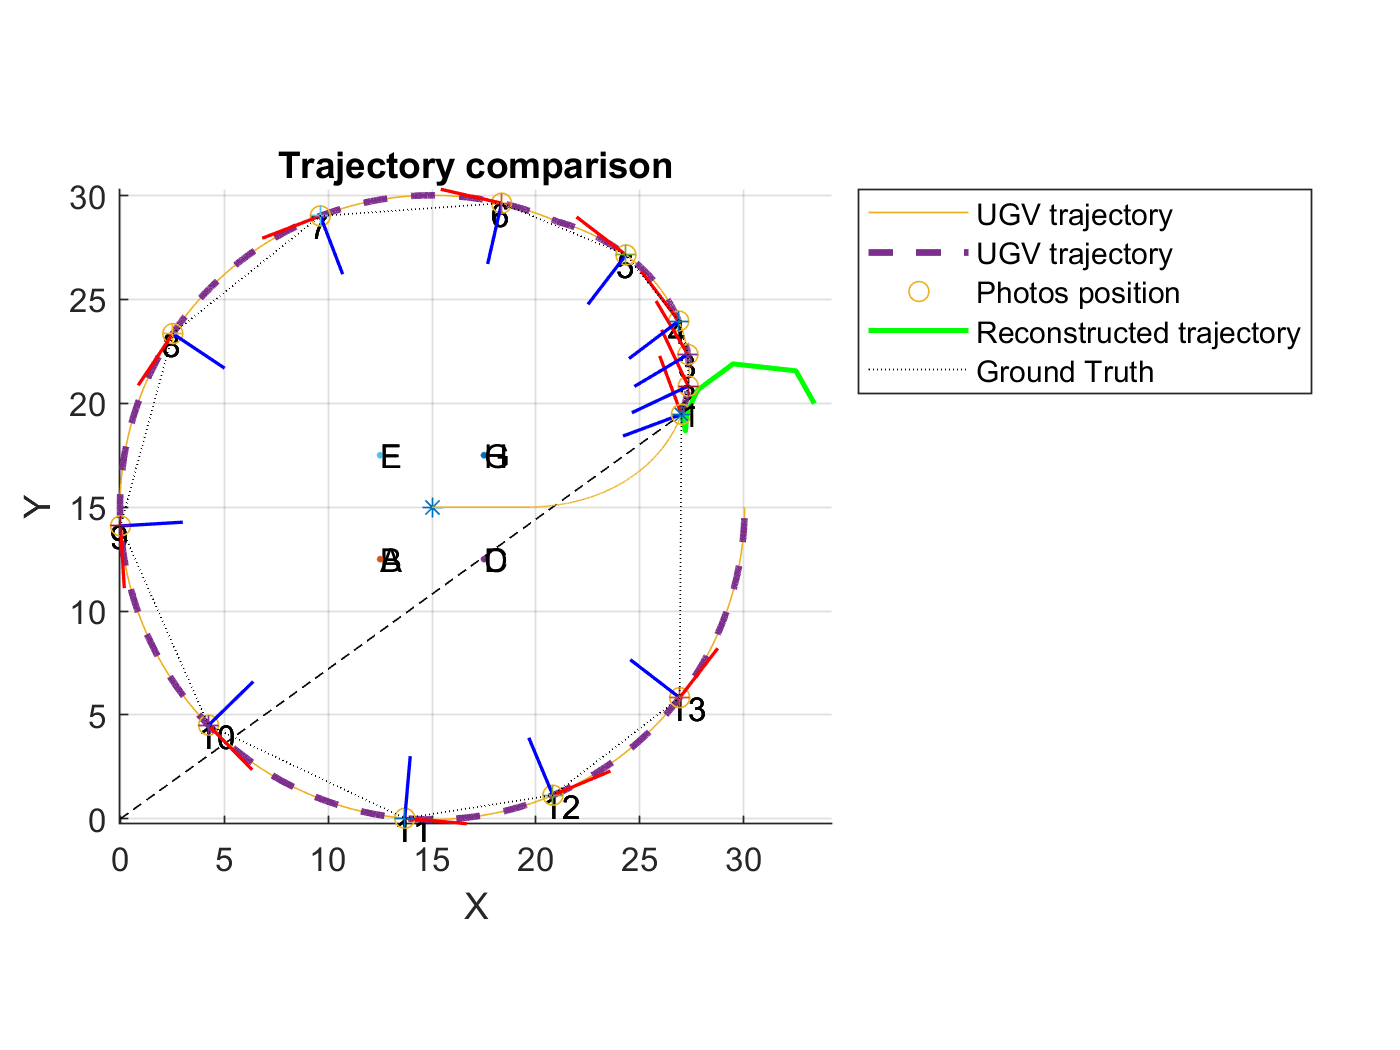

R_perm_yz = [1 0 0; 
             0 0 -1;
              0 1 0]';
est_traj = zeros(3, N + 1);
corrected_est_traj = zeros(3, N + 1);
corrected_est_traj(:, 1) = Twb;
currP = Twb;
for i = 1:N
    if i == N
        j = 1;
    else 
        j = i + 1;
    end
    
    R_temp = R_perm_yz;
    
    for l=2:i
        Rel_R = R_rel(:,:,l-1,l) ;
        
        %ang = deg2rad(getYangle(R_rel(:,:,l-1,l)));
        
        %Rel_R = axang2rotm([0,0,-1,ang]);
        R_temp = R_temp * Rel_R ;
    end
    
  
    
    nextP = currP + R_temp * R_perm_yz * T_scaled_rel(:,:,i,j); %currP +
    corrected_est_traj(:, i + 1) = nextP;
    currP = nextP;
end

%% Plot trajectory
T_history_abs = [T_history_abs T_history_abs(:, 1)];
figure(fig)
set(0,'CurrentFigure',fig)
hold on
plot3(corrected_est_traj(1, :), corrected_est_traj(2, :), corrected_est_traj(3, :), "DisplayName", "Reconstructed trajectory", "Color", "g", 'LineWidth' , 1.5)
plot3(T_history_abs(1, :), T_history_abs(2, :), T_history_abs(3, :), "DisplayName", "Ground Truth", "Color", "k", "Linestyle", ":")
title('Trajectory comparison')
legend('UGV trajectory' , 'UGV trajectory' , 'Photos position',"Reconstructed trajectory" , "Ground Truth")
view(2)

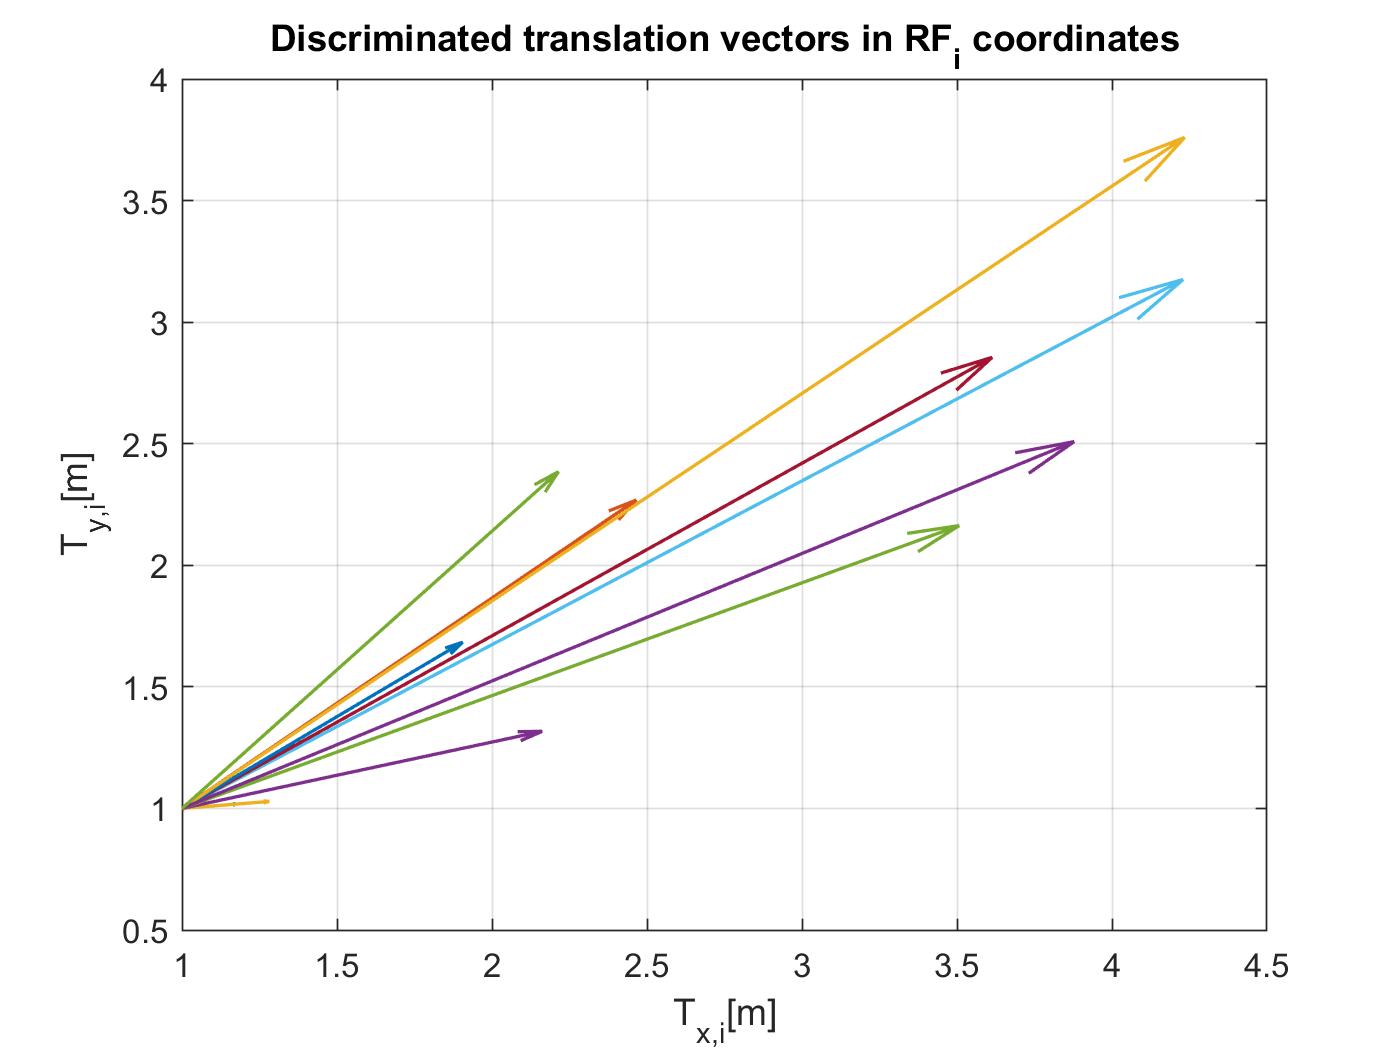

ans = -4.6089

ans = -5.3876

ans = -6.0974

ans = -15.3842

ans = -24.2667

ans = -33.5391

ans = -34.9843

ans = -37.4355

ans = -40.9051

ans = -41.2001

ans = -28.0443

ans = -29.6135


figure()
for h=1:N-1
    quiver(T_scaled_rel(1,1,h,h+1) , T_scaled_rel(3,1,h,h+1),'LineWidth' , 1 , "DisplayName", 'T'+string(h)+string(h+1)+'')
    hold on
    grid on
    %text(T_scaled_rel(1,1,h,h+1) , T_scaled_rel(3,1,h,h+1) , string(h), "Fontsize", 8, "HorizontalAlignment","center");
    %legend('T' + string(h),' vector')
    title('Discriminated translation vectors in RF_i coordinates')
    xlabel('T_{x,i}[m]')
    ylabel('T_{y,i}[m]')
    
    T_scaled_rel(:,:,h,h+1) - GT_rel_T(:,:,h,h+1);
    
    getYangle(R_rel(:,:,h,h+1))
end

L = [5 , -1, -1 , -1 , -1 , -1;
    -1, 5, -1 , -1 , -1 , -1;
    -1, -1 , 5, -1 , -1 , -1;
    -1, -1 , -1 , 5, -1 , -1;
    -1, -1 , -1 , -1 , 5, -1;
    -1, -1 , -1 , -1 , -1 , 5]

L =      5    -1    -1    -1    -1    -1
    -1     5    -1    -1    -1    -1
    -1    -1     5    -1    -1    -1
    -1    -1    -1     5    -1    -1
    -1    -1    -1    -1     5    -1
    -1    -1    -1    -1    -1     5


eig(L)

ans =      0
     6
     6
     6
     6
     6


## Functions

function alpha = getYangle(R)
    alpha = wrapTo180(rad2deg(atan2(R(3,1), R(1,1))));
end

function R = getRfromZ(T, center)
    z_versor = center - T;
    z_versor = z_versor / norm(z_versor);
    y_versor = [0 0 -1];
    x1_versor = cross(y_versor, z_versor);
    r11 = dot(x1_versor, [1 0 0]);
    r21 = dot(x1_versor, [0 1 0]);
    r31 = dot(x1_versor, [0 0 1]);
    r12 = dot(y_versor, [1 0 0]);
    r22 = dot(y_versor, [0 1 0]);
    r32 = dot(y_versor, [0 0 1]);
    r13 = dot(z_versor, [1 0 0]);
    r23 = dot(z_versor, [0 1 0]);
    r33 = dot(z_versor, [0 0 1]);
    R = [r11 r12 r13; r21 r22 r23; r31 r32 r33];
end

